## Loads

clear
load("modelo8.mat")

s = tf("s");

An, Bn

An =          0         0         0    1.0000         0         0
         0         0         0         0    1.0000         0
         0         0         0         0         0    1.0000
         0   -4.4814         0  -11.3179    0.3395         0
         0  114.5125         0  129.1583   -3.8747         0
         0         0         0         0         0   -7.7192


Bn =          0         0
         0         0
         0         0
    1.5267         0
  -17.4221         0
         0  -17.3540


## Simulink

global odeFuncSimulink
odeFuncSimulink = odeFunction(fn, [States; Inputs])

odeFuncSimulink = function_handle with value:
    @(t,in2)[in2(4,:);in2(5,:);in2(6,:);((in2(5,:).*1.191647389643175e-6-in2(4,:).*3.97215796547725e-5+in2(7,:).*5.358018433704305e-6-cos(in2(2,:)).*sin(in2(2,:)).*1.950880702464e-5+in2(5,:).*cos(in2(2,:)).*2.864490655182691e-7-in2(4,:).*cos(in2(2,:)).*9.548302183942302e-6+in2(7,:).*cos(in2(2,:)).*1.287964364881323e-6+in2(5,:).^2.*sin(in2(2,:)).*2.481894498518069e-7-in2(6,:).^2.*cos(in2(2,:)).^2.*sin(in2(2,:)).*2.036413386859035e-7).*(-1.501501501501502e+2))./(cos(in2(2,:)).^2.*2.985984e-4-9.522452360641909e-4);((in2(5,:).*1.463919267691157e-5-in2(4,:).*4.879730892303856e-4+in2(7,:).*6.582237740723648e-5-sin(in2(2,:)).*9.970121020072811e-4-in2(6,:).^2.*sin(in2(2,:).*2.0).*5.203621084630516e-6+in2(5,:).^2.*sin(in2(2,:).*2.0).*1.988665344e-6+in2(5,:).*cos(in2(2,:)).*1.90966043678846e-5-in2(4,:).*cos(in2(2,:)).*6.365534789294868e-4+in2(7,:).*cos(in2(2,:)).*8.586429099208817e-5).*1.501501501501502e+2)./(cos(in2(2,:).*2.0).*2.985984e-4-1.6058920

## Controle LQR 

desired_states = [2 4 5];
q_fo, q_fo(desired_states)

$$q\_fo = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ \text{psi}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right)\\ {\mathrm{Dpsi}}_{t}\left(t\right) \end{array}\right)$$

$$ans = \left(\begin{array}{c} \theta \left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Ar = An(desired_states,desired_states)

Ar =          0         0    1.0000
   -4.4814  -11.3179    0.3395
  114.5125  129.1583   -3.8747


Br = Bn(desired_states,1)

Br =          0
    1.5267
  -17.4221


Cr = Cn(desired_states,desired_states)

Cr =      1     0     0
     0     1     0
     0     0     1


rank(obsv(Ar, Cr)), rank(ctrb(Ar, Br)) 

ans = 3

ans = 3

Q = Cr'*Cr

Q =      1     0     0
     0     1     0
     0     0     1


R = 0.08;

Kr = lqr(Ar, Br, Q, R)

Kr =   -29.2124  -15.6269   -4.5851


sys_mf = ss(Ar - Br*Kr, Br, Cr, 0)

sys_mf =
 
  A = 
           x1      x2      x3
   x1       0       0       1
   x2   40.12   12.54   7.339
   x3  -394.4  -143.1  -83.76
 
  B = 
           u1
   x1       0
   x2   1.527
   x3  -17.42
 
  C = 
       x1  x2  x3
   y1   1   0   0
   y2   0   1   0
   y3   0   0   1
 
  D = 
       u1
   y1   0
   y2   0
   y3   0
 
Continuous-time state-space model.


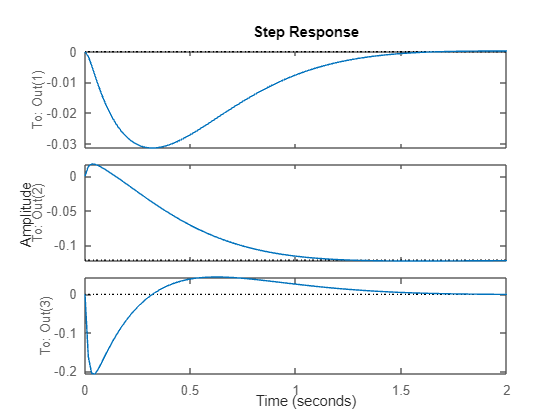

figure
step(sys_mf)

pause(1)

## Controle LQR com integrador (LQI)

Cref = [0 1 0];

sA = size(Ar,1);
sB = size(Br,1);
sC = size(Cref,1);
sIn = size(Br,2);

Ax = [Ar, zeros(sA,sC);
     -Cref, zeros(sC)]

Ax =          0         0    1.0000         0
   -4.4814  -11.3179    0.3395         0
  114.5125  129.1583   -3.8747         0
         0   -1.0000         0         0


Bx = [Br; zeros(sC,sIn)]

Bx =          0
    1.5267
  -17.4221
         0


Q = eye(4);
Q(4,4) = 100

Q =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0   100


R = 0.08;
Kexp = lqr(Ax, Bx, Q, R)

Kexp =   -44.9181  -30.9875   -6.1045   35.3553


Kx = Kexp(1:3)

Kx =   -44.9181  -30.9875   -6.1045


Ki = Kexp(4)

Ki = 35.3553

#### Simulação (close loop)

sys_intern = ss(Ar - Kx*Br, Br, Cref, 0)

sys_intern =
 
  A = 
           x1      x2      x3
   x1  -59.05  -59.05  -58.05
   x2  -63.53  -70.36  -58.71
   x3   55.47   70.11  -62.92
 
  B = 
           u1
   x1       0
   x2   1.527
   x3  -17.42
 
  C = 
       x1  x2  x3
   y1   0   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


integral_action = Ki/s

integral_action =
 
  35.36
  -----
    s
 
Continuous-time transfer function.
Model Properties


sys_cl = feedback(integral_action*sys_intern, 1)

sys_cl =
 
  A = 
           x1      x2      x3      x4
   x1       0       0       8       0
   x2       0  -59.05  -59.05  -58.05
   x3  -6.747  -63.53  -70.36  -58.71
   x4      77   55.47   70.11  -62.92
 
  B = 
           u1
   x1       0
   x2       0
   x3   1.527
   x4  -17.42
 
  C = 
          x1     x2     x3     x4
   y1  4.419      0      0      0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.


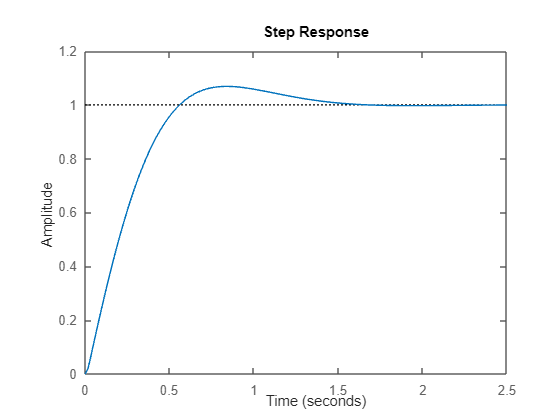

step(sys_cl)

si = stepinfo(sys_cl, "SettlingTimeThreshold", 0.05)

si = struct with fields:
         RiseTime: 0.3937
    TransientTime: 1.0697
     SettlingTime: 1.0697
      SettlingMin: 0.9002
      SettlingMax: 1.0686
        Overshoot: 6.8561
       Undershoot: 0
             Peak: 1.0686
         PeakTime: 0.8320


tau = si.SettlingTime/2

tau = 0.5348

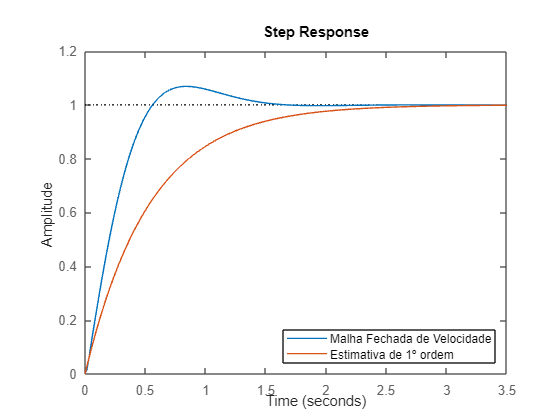

G_dx = 1/(tau*s+1);

figure
step(sys_cl, G_dx)
legend("Malha Fechada de Velocidade", "Estimativa de 1º ordem", "Location", "southeast")

## Controlador para Psi

psi_states = [3 6];
Apsi = An(psi_states,psi_states)

Apsi =          0    1.0000
         0   -7.7192


Bpsi = Bn(psi_states,2)

Bpsi =          0
  -17.3540


Cpsi = [1 0]

Cpsi =      1     0


sys_psi = ss(Apsi, Bpsi, Cpsi, 0)

sys_psi =
 
  A = 
           x1      x2
   x1       0       1
   x2       0  -7.719
 
  B = 
           u1
   x1       0
   x2  -17.35
 
  C = 
       x1  x2
   y1   1   0
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.
Model 

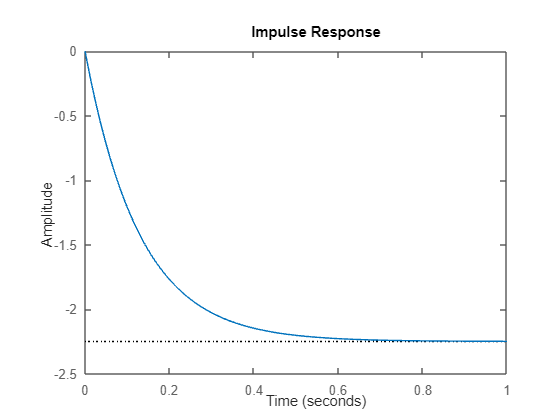

impulse(sys_psi)

G_psi = zpk(sys_psi)

G_psi =
 
    -17.354
  -----------
  s (s+7.719)
 
Continuous-time zero/pole/gain model.
Model Properties


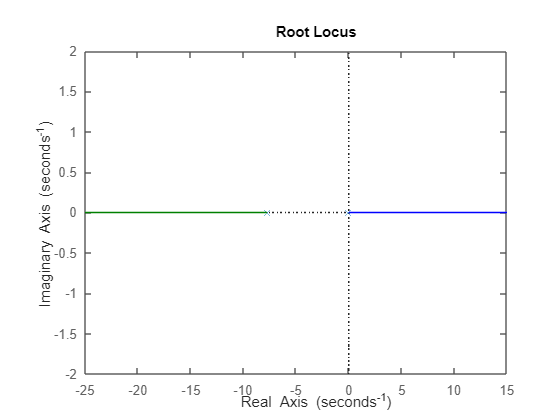

rlocus(G_psi)

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.
Model Properties


C_psi = -3*(s+2)/s

C_psi =
 
  -3 s - 6
  --------
     s
 
Continuous-time transfer function.
Model Properties


F_psi = 2/(s+2);

G_psi_mf = F_psi*feedback(C_psi*G_psi,1)

G_psi_mf =
 
              104.12 (s+2)
  -------------------------------------
  (s+2) (s+2.705) (s^2 + 5.015s + 38.5)
 
Continuous-time zero/pole/gain model.
Model Properties


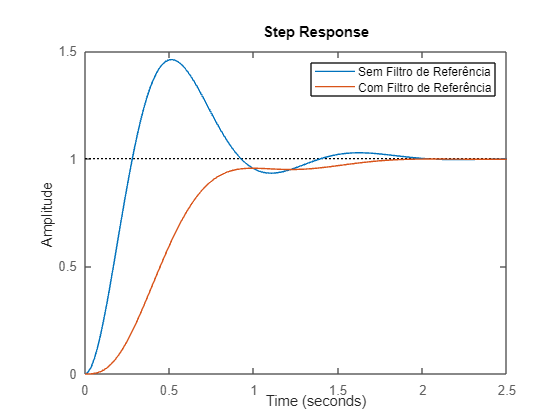

step(feedback(C_psi*G_psi,1), G_psi_mf)
legend("Sem Filtro de Referência", "Com Filtro de Referência")

stepinfo(G_psi_mf, "SettlingTimeThreshold", 0.05)

ans = struct with fields:
         RiseTime: 0.5473
    TransientTime: 1.2529
     SettlingTime: 1.2529
      SettlingMin: 0.9086
      SettlingMax: 0.9990
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9990
         PeakTime: 2.7367


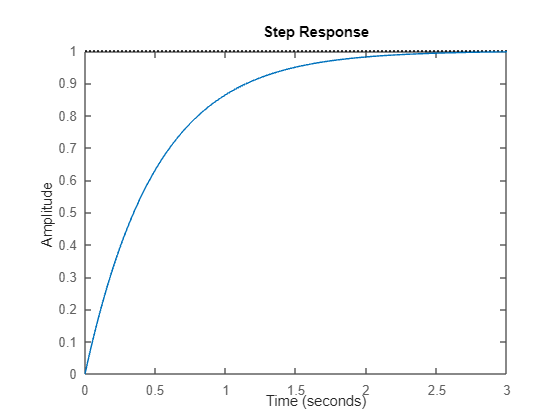

step(F_psi)

F_psi_d = c2d(F_psi, 0.005)

F_psi_d =
 
  0.00995
  --------
  z - 0.99
 
Sample time: 0.005 seconds
Discrete-time transfer function.
Model Properties


Nc = F_psi_d.Numerator{1};
Dc = F_psi_d.Denominator{1};
M = idpoly(Dc, Nc, 'NoiseVariance', 0)

M =
Discrete-time ARX model: A(z)y(t) = B(z)u(t)
  A(z) = 1 - 0.99 z^-1                      
                                            
  B(z) = 0.00995 z^-1                       
                                            
Sample time: unspecified
  
Parameterization:
   Polynomial orders:   na=1   nb=1   nk=1
   Number of free coefficients: 2
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                                         
Created by direct construction or transformation. Not estimated.
 
Model Properties


M.A, M.B

ans =     1.0000   -0.9900


ans =          0    0.0100


## Dados Reais

dados_reais = readtable("dados_controle_real.txt")

dados_reais = 9358×7 table
      t        u      ref_dx    ref_psi      dx        theta       psi  
    ______    ____    ______    _______    _______    _______    _______

         0     285      0          0        10.098    -0.0137          0
    0.0049     136      0          0         5.049    -0.0239     0.0001
    0.0087     -25      0          0        2.5806    -0.0749     0.0003
    0.0127    -276      0          0        1.3838    -0.2278      0.001
    0.0167    -267      0          0        0.7106     -0.363     0.0019
    0.0199     518      0          0        0.2805     -0.111     0.0014
    0.0237    -147      0          0       -0.0094    -0.1804      0.002
    0.0268     262      0          0       -0.0795    -0.0501          0
    

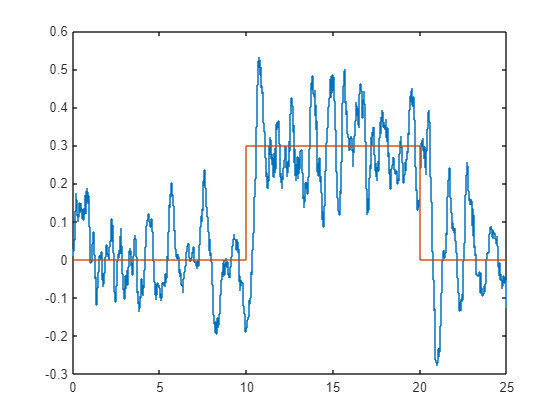

dados_reais = dados_reais(dados_reais.t >= 5,:);
dados_reais.t = dados_reais.t - 5;


figure
stairs(dados_reais.t, smoothdata(dados_reais.dx, "movmedian", 50))
hold on
stairs(dados_reais.t, dados_reais.ref_dx)

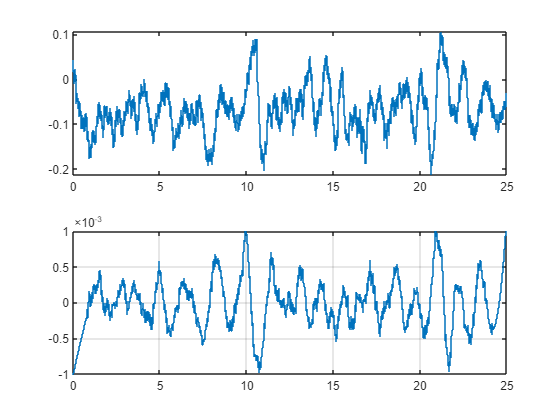

figure
subplot(2,1,1)
stairs(dados_reais.t, smoothdata(dados_reais.theta, "movmedian", 1))
subplot(2,1,2)
stairs(dados_reais.t, smoothdata(gradient(dados_reais.theta), "sgolay", 500))
grid on, ylim(1e-4 * [-10 10])

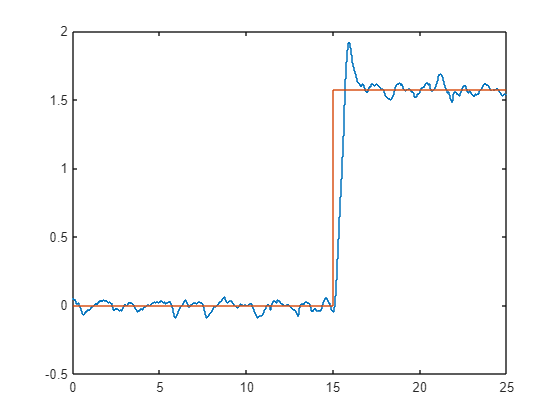

figure
stairs(dados_reais.t, smoothdata(dados_reais.psi, "movmedian", 1))
hold on
stairs(dados_reais.t, dados_reais.ref_psi)